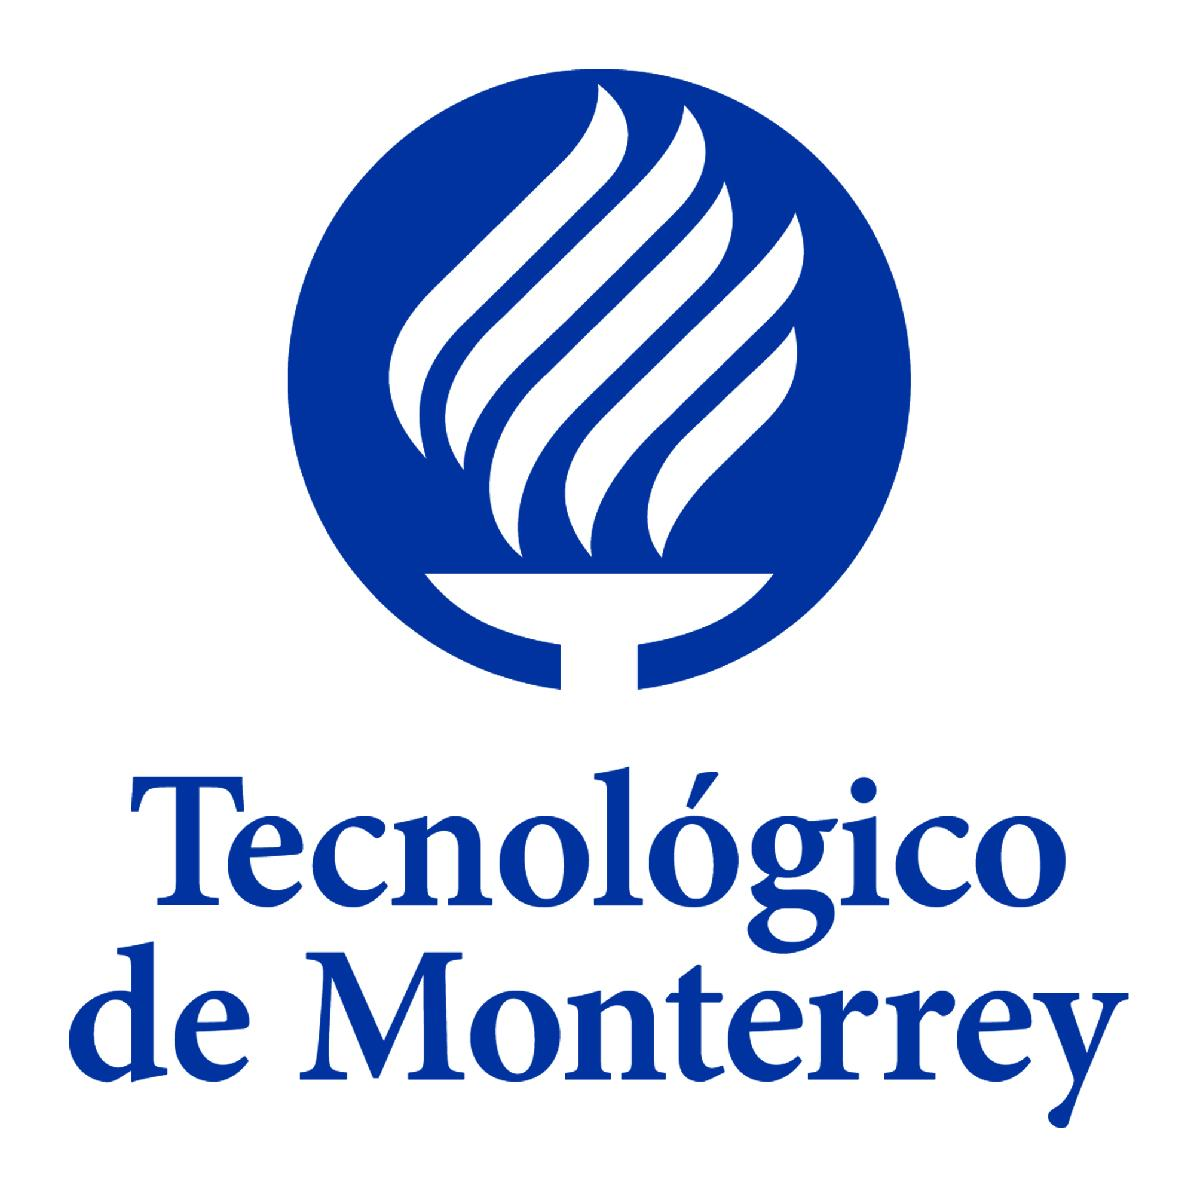 

**Simulador 1. Simulador de Coulomb**

Presentado por:

Daniel Emilio Fuentes Portaluppi - A01708302

Profesor:

Ernesto Momox Beristain

F1013B Modelación computacional de sistemas eléctricos | Grupo 201

Viernes, 8 de abril del 2022

clear all; clc;

Variables constantes

a = true;
S = 0;

Solicita la carga inicial además del vector inicial.

Q = input("Introduce tu carga principal: ")

Q = 1.0000e-08

Rx = input("Introduce 'x' de tu vector: ")

Rx = 0

Ry = input("Introduce 'y' de tu vector: ")

Ry = 3

Rz = input("Introduce 'z' de tu vector: ")

Rz = 1

R1 = [Rx,Ry,Rz]

R1 =      0     3     1


Aquí comienza un bucle donde se realiza la sumatoria.

while a == true
    %Solicita el otro vector y su carga
    QK = input("Introduce tu otra carga: ")
    R2x = input("Introduce 'x' de tu otro vector: ")
    R2y = input("Introduce 'y' de tu otro vector: ")
    R2z = input("Introduce 'z' de tu otro vector: ")
    R2 = [R2x,R2y,R2z]
    
    %Aquí calcula el módulo de la resta de los vectores
    r = R1-R2
    r_norm = sqrt(r(1)^2+r(2)^2+r(3)^2)
    
    %Aquí hace la sumatoria
    S = S + QK * r/(r_norm)^3 

    %Pregunta si se desea añadir otra carga
    b = input("¿Quiere añadir otra carga? Si = 1 / No = 2: ")
    %Si la respuesta es "si" vuelve a comenzar, si la respuesta es "no" 
    %va al siguiente paso
    if b == 1
        a = true;
    elseif b == 2
        a = false;
    else
        a = false;
        disp("ERROR");
    end
end

QK = 1.0000e-03

R2x = 3

R2y = 2

R2z = -1

R2 =      3     2    -1


r =     -3     1     2


r_norm = 3.7417

S = 1.0e-04 *

   -0.5727    0.1909    0.3818


b = 1

QK = -0.0020

R2x = -1

R2y = -1

R2z = 4

R2 =     -1    -1     4


r =      1     4    -3


r_norm = 5.0990

S = 1.0e-04 *

   -0.7236   -0.4125    0.8344


b = 2

Aquí se multiplica nuestra sumatoria por la carga original y  se divide entre la constante de la permitividad del vacío. 

Además también se calcula el campo eléctrico que es esa fuerza eléctrica entre nuestra carga original.

f_electrica = S * Q / (10e-9 / 9)

f_electrica = 1.0e-03 *

   -0.6512   -0.3713    0.7509


c_electrico = f_electrica/ Q

c_electrico = 1.0e+04 *

   -6.5121   -3.7128    7.5094



f_text = "Tu fuerza eléctrica es: "...
+ f_electrica(1) + " " + f_electrica(2)...
+ " " + f_electrica(3);

c_text = "Tu campo eléctrico es: "...
+ c_electrico(1) + " " + c_electrico(2)... 
+ " " + c_electrico(3);

Por último imprime las respuestas de la fuerza eléctrica y el campo eléctrico.

disp(f_text)

Tu fuerza eléctrica es: -0.00065121 -0.00037128 0.00075094


disp(c_text)

Tu campo eléctrico es: -65120.5104 -37128.0037 75093.9724
